Three set of data obtained:

Dataset            File Name                                Details

1                      Tx1Rx1_T-mid_R1-L                Left Antenna = Rx1; Mid Antenna = Tx1; Right Antenna = NA; plate @ 45 cm

2                      Tx1Rx1_T-L_R1-mid                Left Antenna = Tx1; Mid Antenna = Rx1; Right Antenna = NA; plate @ 45 cm

3                      Tx1Rx1_T-L_R1-mid_plate2    Left Antenna = Tx1; Mid Antenna = Rx1; Right Antenna = NA; plate @ 75 cm

Objectives:

    1. Compare datasets 1 and 2 to verify whether antennas are identical.

    2. Compare datasets 2 and 3 to verify range calculation.

% Objective-1: Compare datasets 1 and 2 to verify whether antennas are identical.
dataDir = "../Data/2021-09-30/"

dataDir = "../Data/2021-09-30/"

dataset3 = load_ancortek_data(fullfile(dataDir, "Tx1Rx1_T-L_R1-mid_plate2.mat"))

dataset3 = struct with fields:
         props: [1×1 struct]
    datamatrix: [2×1999×128 double]


data3PulseAvgd = squeeze(mean(dataset3.datamatrix, 2));
size(data3PulseAvgd)

ans =      2   128


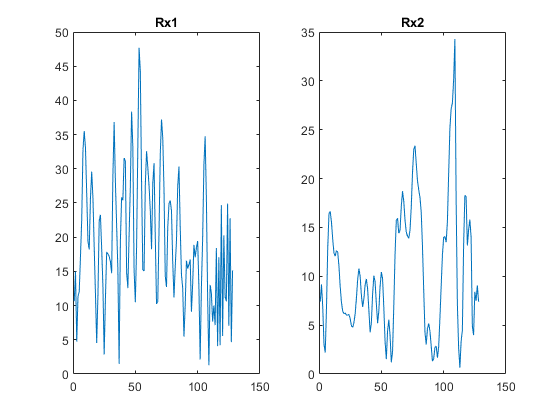


figure()
subplot(1, 2, 1)
xGates = 1:length(data3PulseAvgd(1, :));
plot(xGates, abs(data3PulseAvgd(1, :)))
title("Rx1")

subplot(1, 2, 2)
plot(xGates, abs(data3PulseAvgd(2, :)))
title("Rx2")

dataset3 = load_ancortek_data(fullfile(dataDir, "Tx1Rx1_T-L_R1-mid_plate2_new attempt.mat"))

dataset3 = struct with fields:
         props: [1×1 struct]
    datamatrix: [2×1999×128 double]


data3PulseAvgd = squeeze(mean(dataset3.datamatrix, 2));
size(data3PulseAvgd)

ans =      2   128


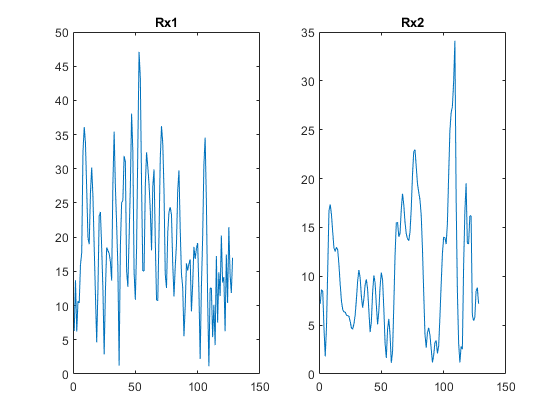


figure()
subplot(1, 2, 1)
xGates = 1:length(data3PulseAvgd(1, :));
plot(xGates, abs(data3PulseAvgd(1, :)))
title("Rx1")

subplot(1, 2, 2)
plot(xGates, abs(data3PulseAvgd(2, :)))
title("Rx2")

c = 299792458;   % speed of ligth [m/s]
fslope = dataset3.props.fslope

fslope = 2.0000e+12

dR = dataset3.props.dR

dR = 0.0749

dataset3.props.RangeMax

ans = 9.5934

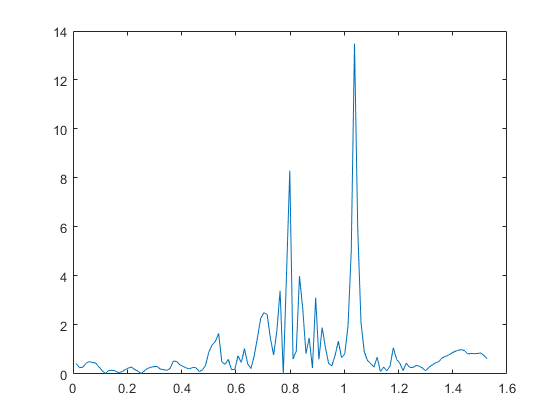


x1 = data3PulseAvgd(1, :);
fBaseband = fftshift(fft(x1)) / length(x1);


figure()
plot((1:length(x1)) * dR /2/pi, abs(fBaseband))